% PRANJAL KUMAR
% CSE 2k18
% BTECH/10164/18

1.Write a program that declares three integers and prints the largest and smallest in the group.

a=2;
b=3;
c=5;
%Code for Maximum
max = a;
if max<b
    max=b;
end
if max<c
    max=c;
end
%code for Minimum
min = a;
if min>b
    min = b;
end
if min>c
    min = c;
end

fprintf("Maximum = %i",max);

Maximum = 5

fprintf("Minimum = %i",min);

Minimum = 2

2. Program that accepts two numbers from the users and prints their sum.

a = input("Enter first number: ");
b = input("Enter second number: ");
c = a+b;
fprintf("First number: %i",a);

First number: 3

fprintf("Second number = %i",b);

Second number = 8

fprintf("Sum = %i",c);

Sum = 11

3. Write a program to calculate simple Interest.

P = input("Enter the Principle: ");
R = input("Enter the percentage of Rate: ");
T = input("Enter the time in years: ");
SI = P*R*T/100;
fprintf("Principle: %i",P);

Principle: 5000

fprintf("Rate: %i",R);

Rate: 4

fprintf("Time: %i",T);

Time: 4

fprintf("Simple Interest: %i",SI);

Simple Interest: 800

4.Write a program to check find that given year is leap year or not

flag = 0;
y = input("Enter the year you want to check: ");
if mod(y,4)==0&&mod(y,100)~=0
    flag = 1;
elseif mod(y,100)==0&&mod(y,400)==0
    flag = 1;
end

if flag==1
    fprintf("%i is a leap year",y);
else
    fprintf("%i is not a leap year",y);
end

2020 is a leap year

5. Implementing linear search and Binary search

%%Linear Search
arr = [1,4,2,5,6,7,10,3];
x = input("Enter the element you want to search: ");
pos = -1;
for index = (1:length(arr))
    if x == arr(1,index)
        pos = index;
    end
end
fprintf("x = %i",x);

x = 5

if pos==-1
    disp("Element not found");
else
    fprintf("Element found at pos: %i",pos);
end

Element found at pos: 4



%%Binary Search

arr = [12,34,35,67,78,89,90];
x = input("Enter the element you want to search: ");
s = 1;
e = length(arr);
pos = -1;
while(s<e)
    mid = floor((s+e)/2);
    if (arr(1,mid)==x)
        pos = mid;
        break
    end
    if (arr(1,mid)>x)
        e=mid-1;
    end
    if(arr(1,mid)<x)
        s=mid+1;
    end
end

if pos==-1
    disp("Element not found");
else
    fprintf("Element found at pos: %i",pos);
end

Element found at pos: 2

6.Factorial of a given number

x = input("Enter a number to find its factorial: ");
fact = 1;
for index = (1:x)
    fact = fact * index;
end

fprintf("Factorial of the %i is: %i",x,fact);

Factorial of the 5 is: 120

7.Find wether a given number is palindrome or not.

x = input("Enter a number to check wether it is palindrome or not: ");
rev_num = 0;
temp = x;
while(x>0)
    rev_num = rev_num * 10;
    rev_num = rev_num + mod(x,10);
    x = floor(x/10);
end

if (temp==rev_num)
    disp("The number is palindrome");
else
    disp("The number is not palindrome");
end

The number is palindrome


8.Check wether a given number is Armstrong or not.

x = input("Enter a number to check wether it is armstrong or not: ");
temp = x;
check = 0;
while(x>0)
    last_digit = mod(x,10);
    x = floor(x/10);
    check = check + last_digit*last_digit*last_digit;
end

if temp==check
    disp("The number is Armstrong ");
else
    disp("The number is not Armstrong");
end

The number is Armstrong 


9.Print Fibonacci series

first = 0;
second = 1;
x = input("Enter the number of terms you want to print from Fibonacci series: ");
fprintf("x = %i",x);

x = 10

i = 0;
while(i<x)
    if(x==1)
        disp(first);
        break;
    elseif(x==2)
        fprintf("%i %i",first,second);
        break;
    else
        fprintf("%i ",first);
        third = first+second;
        first = second;
        second = third;
    end
    i = i+1;
end

0 1 1 2 3 5 8 13 21 34 

10. Convert decimal numbers to binary numbers.

x = input("Enter a number to convert it into decimal form: ");
temp = x;
s = "";
while x>0
    if(mod(x,2)==0)
        s=strcat(s,"0");
    else
        s=strcat(s,"1");
    end
    x = floor(x/2);
end
s = reverse(s);
fprintf("Number entered: %i",temp);

Number entered: 4

str = strcat("Number in binary form: ",s);
disp(str);

Number in binary form: 100


11.Adding two numbers using functions.

% function for addition

x = input("Enter first number: ");
y = input("Enter second number: ");
fprintf("x = %i",x);

x = 3

fprintf("y = %i",y);

y = 5

sum = ADD(x,y);   % function defined at the end of file
fprintf("Sum of two numbers: %i",sum);

Sum of two numbers: 8

12. Calculating average using function.

n = input("Enter the number of numbers for which you want to calculate average: ");
i = 0;
sum=0;
while(i<n)
    i = i+1;
    num = input("Enter a number: ");
    sum = sum+num;
end
avg = sum/n;
fprintf("n = %i",n);

n = 5

fprintf("Average: %i",avg);

Average: 3

13.Program to find area of rectangle

l = input("Enter length of rectangle: ");
b = input("Enter breadth of rectangle: ");
fprintf("l = %i",l);

l = 12

fprintf("b = %i",b);

b = 34

fprintf("Area = %i",l*b);

Area = 408

14. Generation of pyramid.

n = input("Enter the number of lines of pattern to be printed: ");
for i = (1:n)
    for j = (1:n-i)
        fprintf("  ");
    end
    fprintf("\n");
    for j = (1:i)
        fprintf(" *");
    end
    fprintf("\n");
end

 *

 * *

 * * *

 * * * *

 * * * * *

for k = (1:n-1)
    for j = (1:k)
        fprintf("  ");
    end
    fprintf("\n");
    for j = (1:n-k);
        fprintf(" *");
    end
    fprintf("\n");
end

 * * * *

 * * *

 * *

 *

15(a). Read a Gray Scale image and plot the image on histogram.

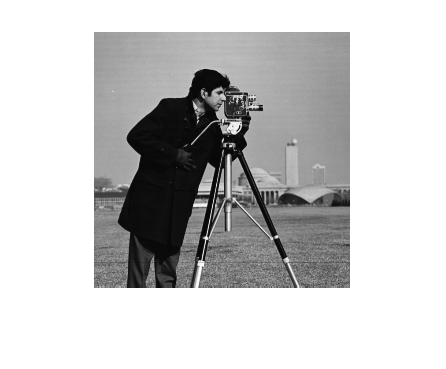

img = imread("cameraman.tif");
imshow(img);

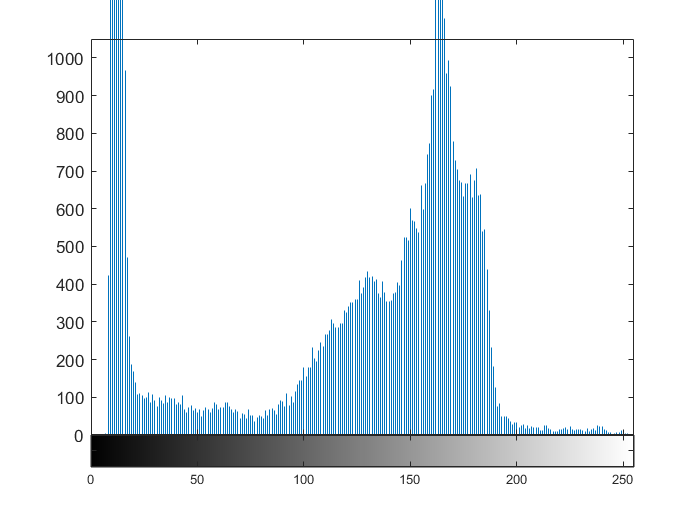

figure;
imhist(img);

15(b). Read a gray scale image and plot the image histogram.

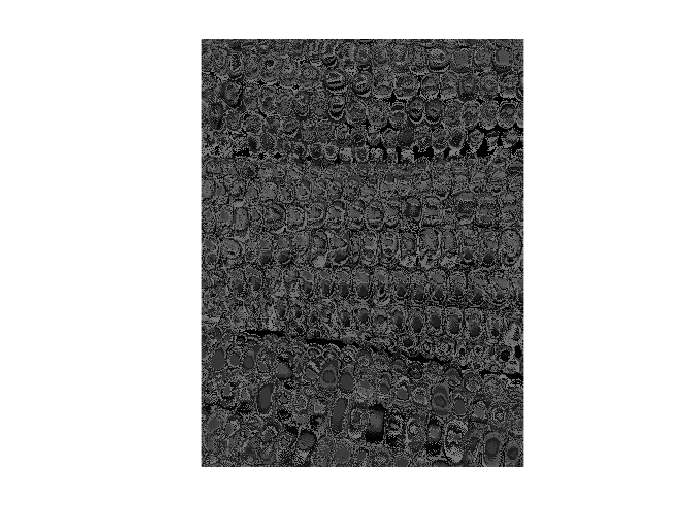

img = imread("corn.tif");
imshow(img);

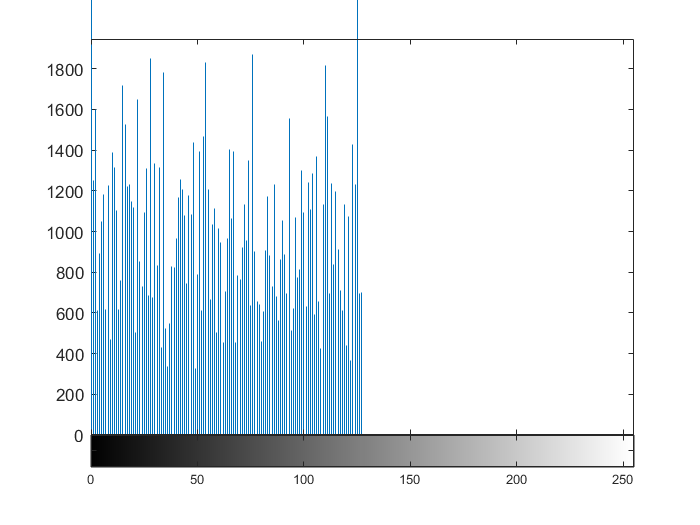

figure;
imhist(img);

15(c). Read a gray scale image and find its Weber's ratio.

img = imread("cameraman.tif");
contrast = max(img(:))-min(img(:));
m = mean(img(:));
fprintf("Webers Ratio: %i",contrast/m);

Webers Ratio: 2

15(d).Read a Gray Scale image and convert it into Binary image.

img = imread("corn.tif");
binary_img = convert2binary(img);
imshow(binary_img);

function binary = convert2binary(img)
    [x, y] = size(img);
    sum=0;
    for i = (1:x)
        for j = (1:y)
            sum = sum+img(i,j);
        end
    end
    threshold = sum/(x*y);
    
    binary=zeros(x,y);
    
    for i=(1:x)
        for j=(1:y)
            if (img(i,j)>=threshold)
                binary(i,j)=1;
            else
                binary(i,j)=0;
            end
        end
    end
end

function res = ADD(x,y)
   res = x+y;   
end